system('sh split.sh');
f = figure('Visible','on');

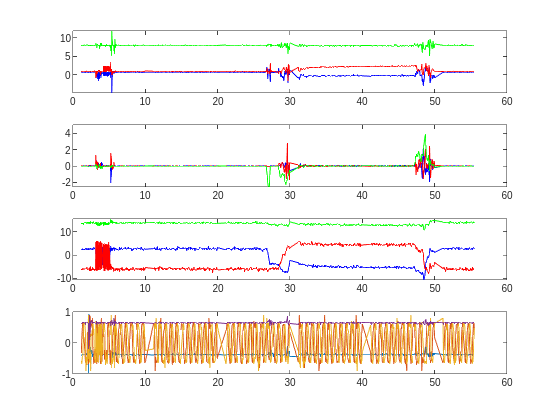

while true
acc = readtable("acc.txt");
gyro = readtable("gyro.txt");
mag = readtable("mag.txt");
quat = readtable("quat.txt");

minHeight = min([height(quat),height(acc),height(gyro),height(mag)]);

data = [quat(1:minHeight,:), acc(1:minHeight,:), gyro(1:minHeight,:), mag(1:minHeight,:)];
data = sortrows(data,'t','ascend');
t = data.t;


s = tiledlayout("vertical");
nexttile
plot(t,data.ax, 'b');
hold on;
plot(t,data.ay,'r');
plot(t,data.az,'g');

nexttile
plot(t,data.gx, 'b');
hold on;
plot(t,data.gy, 'r');
plot(t,data.gz, 'g');

nexttile
plot(t,data.mx, 'b');
hold on;
plot(t,data.my, 'r');
plot(t,data.mz, 'g');

nexttile
plot(t,data.q0);
hold on;
plot(t,data.qx);
plot(t,data.qy);
plot(t,data.qz);

system('sh split.sh');
pause(0.5);
clear s
end